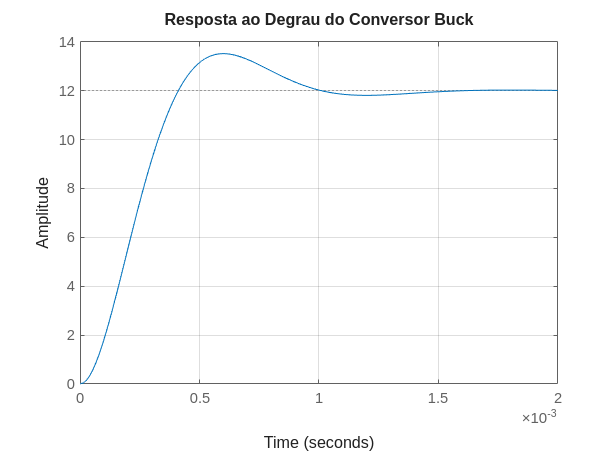



load('dados_sinal.mat', 'y_ret', 'Fs', 't'); 
%% Conversor Buck - Análise Completa
% Parâmetros do circuito
L = 1.752e-3;   % Indutância (H)
C = 14.48e-6;   % Capacitância (F)
R = 10;     % Resistência de carga (Ω)

% Função de transferência usando operadores
s = tf('s');
G_buck = (1/(L*C)) / (s^2 + (1/(R*C))*s + 1/(L*C));

% Resposta ao degrau para tempo de subida e acomodação
figure;
step( 12* G_buck);
title('Resposta ao Degrau do Conversor Buck');
grid on;

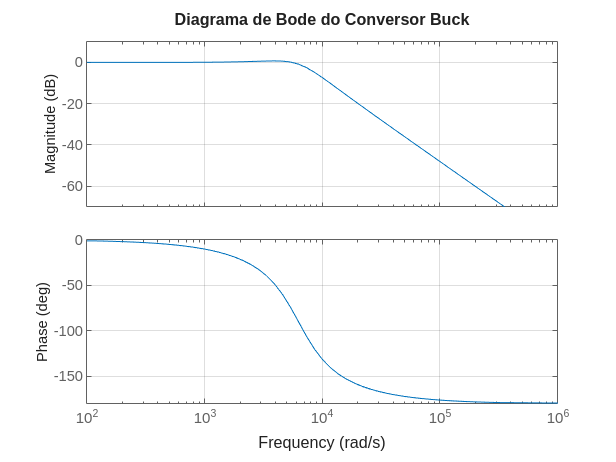


% Diagrama de Bode
figure;
bode(G_buck);
title('Diagrama de Bode do Conversor Buck');
grid on;

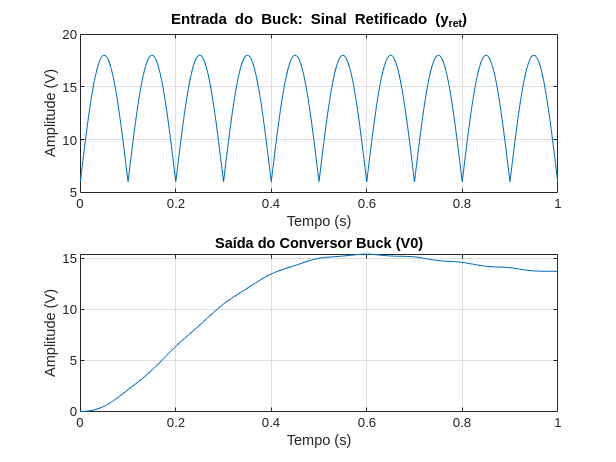


% Simulação com o sinal retificado (y_ret)
V0_buck = lsim(G_buck, y_ret, t);

load('dados_sinal.mat', 'y_ret', 'Fs', 't'); 

% Plotagem da entrada vs. saída
figure;
subplot(2,1,1);
plot(t*1000, y_ret);
title('Entrada do Buck: Sinal Retificado (y_{ret})');
xlabel('Tempo (s)');
ylabel('Amplitude (V)');
grid on;

subplot(2,1,2);
plot(t*1000, V0_buck);
title('Saída do Conversor Buck (V0)');
xlabel('Tempo (s)');
ylabel('Amplitude (V)');
grid on;

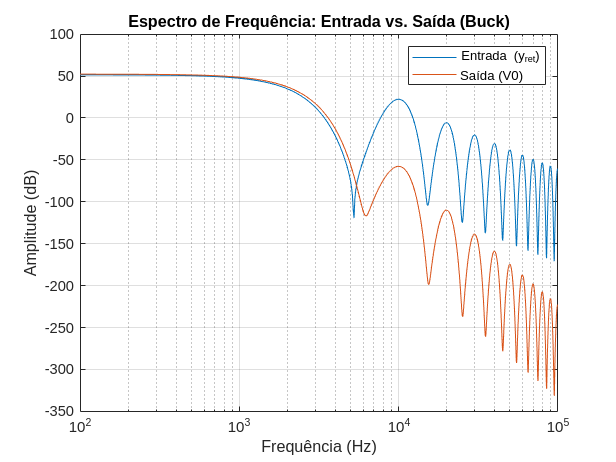


% Análise de harmônicas
figure;
[P_vin, f_vin] = pspectrum(y_ret, Fs);
[P_v0, f_v0] = pspectrum(V0_buck, Fs);

semilogx(f_vin, 20*log10(P_vin));
hold on;
semilogx(f_v0, 20*log10(P_v0));
hold off;
xlim([1e2 1e5]);
title('Espectro de Frequência: Entrada vs. Saída (Buck)');
xlabel('Frequência (Hz)');
ylabel('Amplitude (dB)');
legend('Entrada (y_{ret})', 'Saída (V0)');
grid on;

% Salvar saída
save('V0_buck.mat', 'V0_buck', 't', 'Fs');
disp('Saída do Buck salva em dados/V0_buck.mat');

Saída do Buck salva em dados/V0_buck.mat
